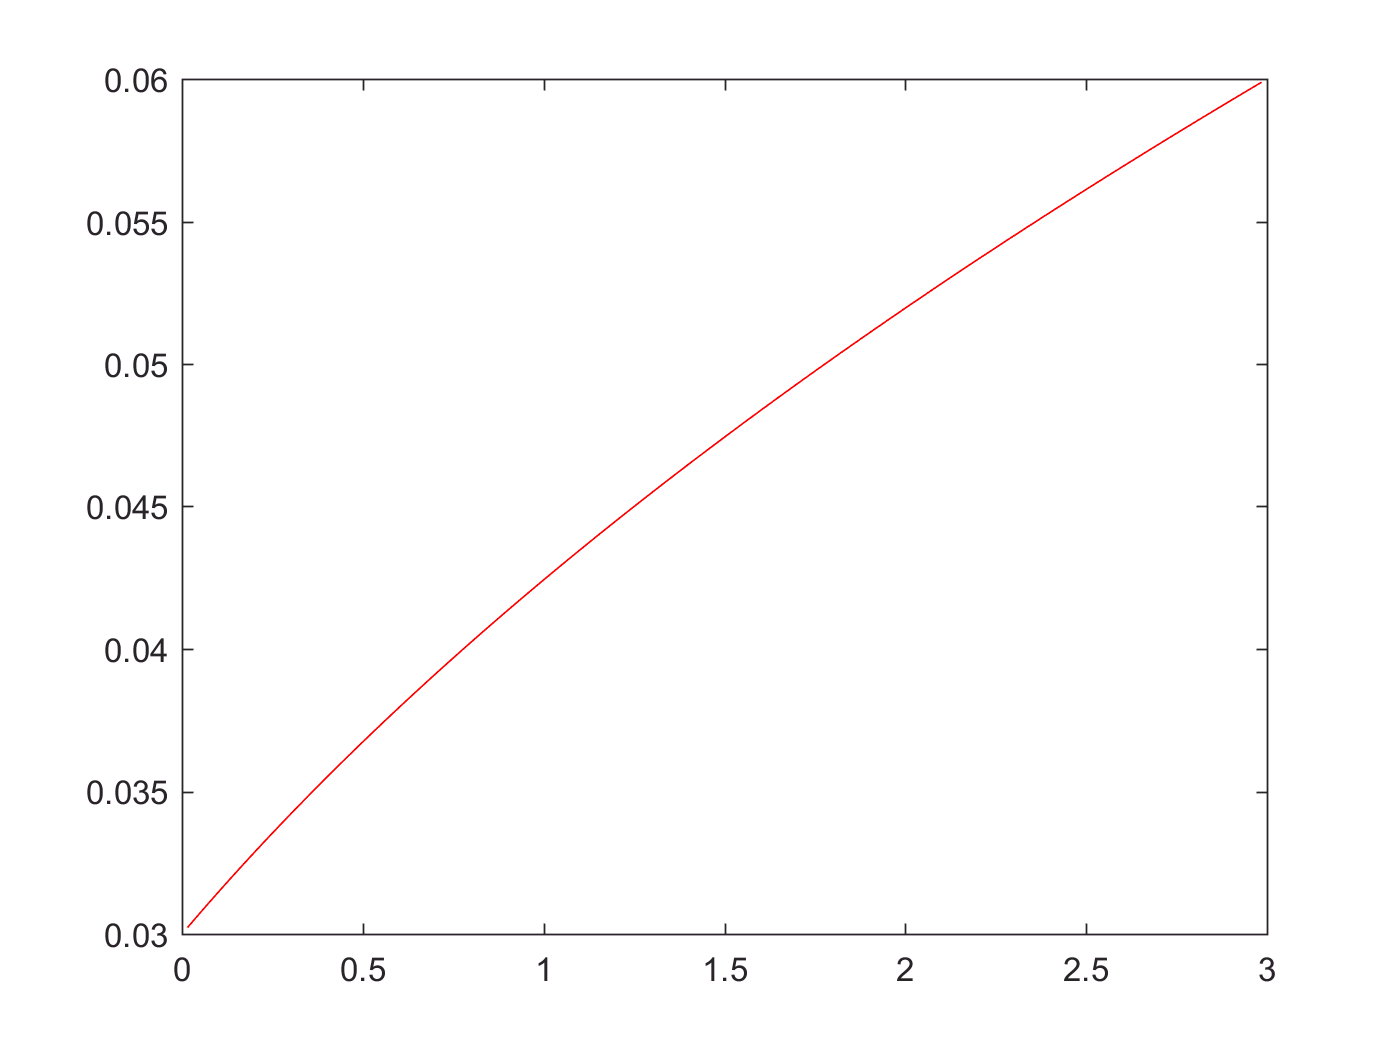

n_vec = 10:100;
ans(1:91) = 14/3;
sum = [];
for i = 1:length(n_vec)
    sum = [sum,TrapApproxS(n_vec(i))];
end

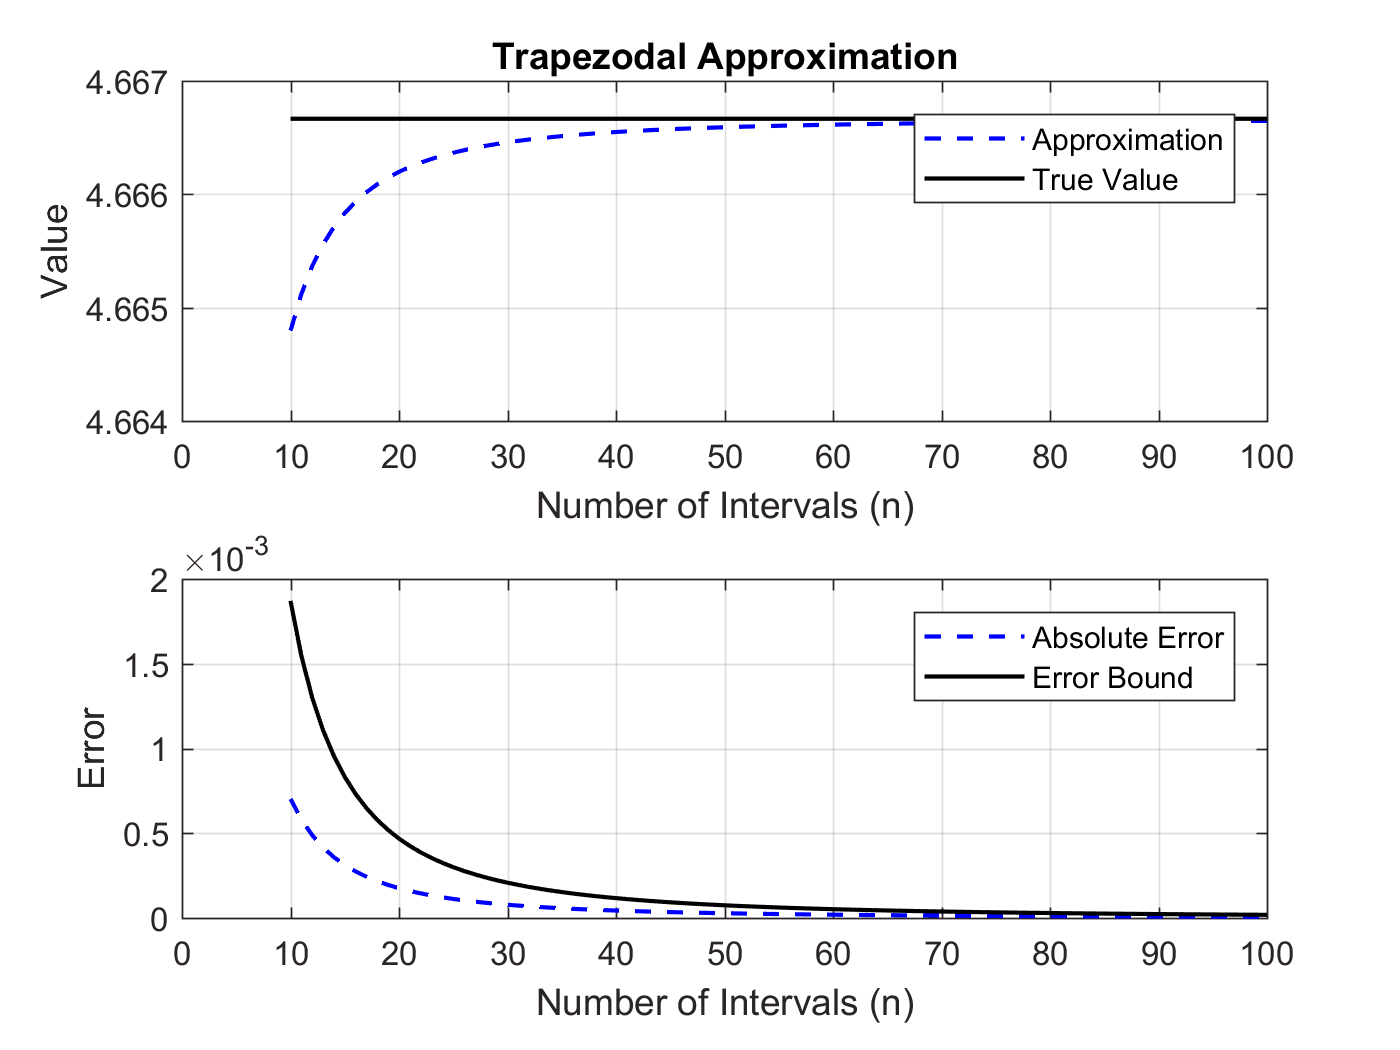

subplot(2,1,1)
plot(n_vec,sum,'--b','Linewidth', 1.25);
hold on
plot(n_vec,ans,'-k', 'Linewidth', 1.25);
legend('Approximation', 'True Value');
title('Trapezodal Approximation');
xlabel('Number of Intervals (n)');
ylabel('Value');
xlim([0 100]);
grid on
hold off

%Error Analysis
%Numerical Error
syms f(x) ff(x) fff(x);
f(x) = sqrt(x+1);
ff(x) = diff(f,x);
fff(x) = diff(ff(x),x);
k = max(fff(0), fff(3));
numerr = [];
for n = 10:100
    numerr = [numerr, abs(((3-0)^3*k)/(12*n^2))];
end
subplot(2,1,2)
plot(n_vec,numerr,'--b', 'Linewidth', 1.25)
hold on

%Exact Error
syms F(x);
F(x) = int(f(x),x,0,3);
exterr(1:91) = abs(sum-F(x));
plot(n_vec,exterr,'-k', 'Linewidth', 1.25)
legend('Absolute Error', 'Error Bound')
xlabel('Number of Intervals (n)')
ylabel('Error')
xlim([0 100])
grid on
hold off